Definition af kendte størrelser:

m = 1.5;
L = 1.2^(1/3); 
EI = 10;
k = 12*EI/L^3;
dof = 2;
zeta = [0.05; 0.05];
F0 = [0; 4];
Omega = 5.5;
F = F0 * cos(Omega*t);

Modellering af systemet:

K = 2 * [k -k ;-k 2*k]; %Stivhedsmatrice
M = m*eye(dof); %Massematrice
[Phi, Lambda] = eig(K,M); %Egenvektorer og dertilhørende egenværdier
omegaN = sqrt(diag(Lambda)); %Udtræk egenfrekvenser fra egenværdier
[omegaN, origOrder] = sort(omegaN); %Sorter egenfrekvenser mens vi tracker den oprindelige rækkefølge for at kunne sortere egenvektorer
Phi = Phi(:, origOrder); %Sorter egenvektorer i samme rækkefølge som egenfrekvenser
Phi = Phi./Phi(1,:); %Smart trick fra løsningforslag – her skaleres alle egenvektorer med deres første index idet egenvektorer ikke er entydige og derfor skalerbare

Standard-tidsintervaller til beregninger:

N = 1500; %Antal "tidspunkter"
dt = 0.01; %Afstand mellem "tidspunkter"
t = 0:dt:(N-1)*dt; %Alle "tidspunkter"

Dæmpningsmatricen:

MTilde = Phi' * M * Phi;
CTilde = diag(2.*zeta.*diag(MTilde).*omegaN);
C = (Phi')^-1 * CTilde * Phi^-1

C =     1.5492   -0.7746
   -0.7746    2.3238


Partikulær løsning af modaldekoblet system:

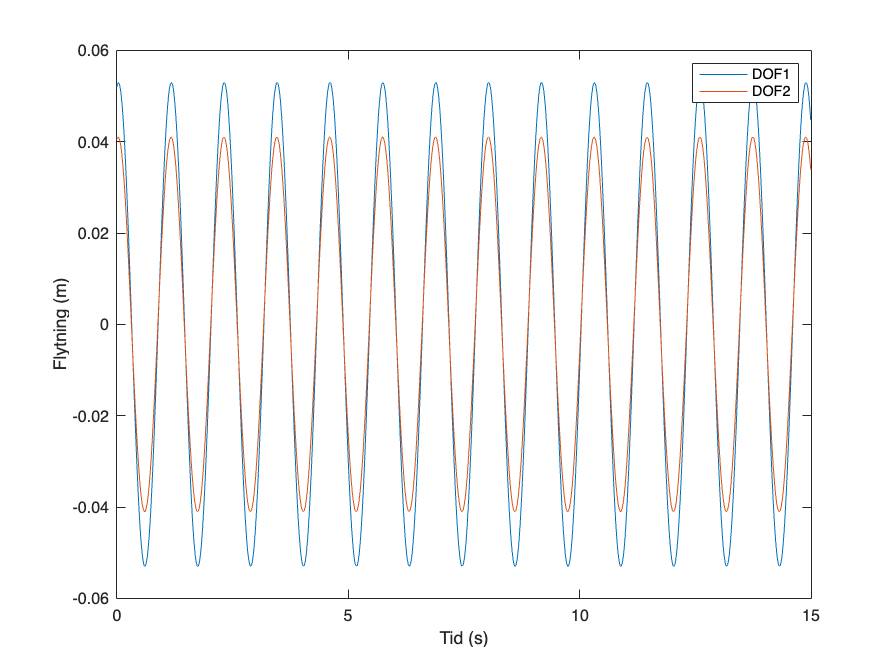

KTilde = Phi' * K * Phi;
FTilde = Phi' * F;
qPart = zeros(dof, N);
for jj=1:dof
    Bj = FTilde(jj,1)/sqrt((KTilde(jj,jj) - MTilde(jj,jj)*Omega^2)^2 + CTilde(jj,jj)^2*Omega^2);
    epsj=atan2(CTilde(jj,jj) * Omega, (KTilde(jj,jj) - MTilde(jj,jj) * Omega^2));
    qPart(jj,:) = Bj * cos(Omega*t-epsj);
end
dPart = Phi * qPart;

figure; plot(t, dPart(1,:), t, dPart(2,:))
xlabel('Tid (s)'); ylabel('Flytning (m)')
legend('DOF1','DOF2')

Trunkeret løsning

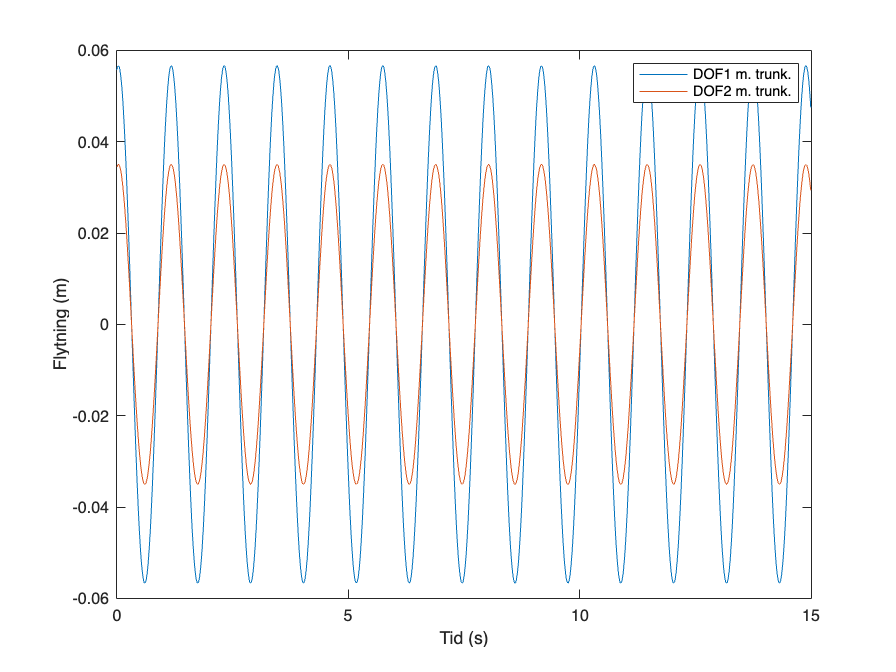

modeToKeep = 1;
dPartTrunc = Phi(:, modeToKeep) * qPart(modeToKeep, :);


figure; plot(t, dPartTrunc(1,:), t, dPartTrunc(2,:))
xlabel('Tid (s)'); ylabel('Flytning (m)')
legend('DOF1 m. trunk.', 'DOF2 m. trunk.')

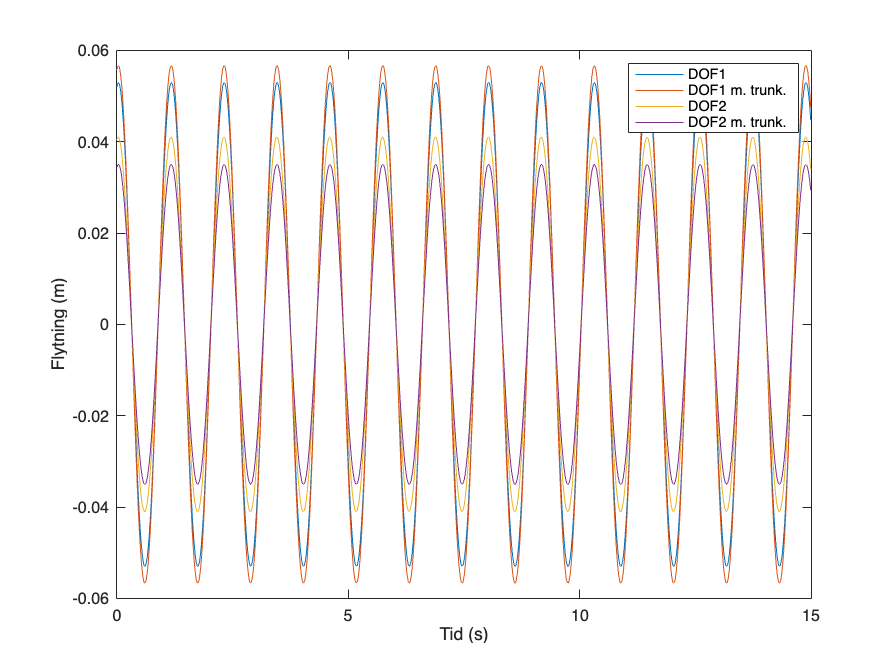



figure; plot(t, dPart(1,:), t, dPartTrunc(1,:), t, dPart(2,:), t, dPartTrunc(2,:))
xlabel('Tid (s)'); ylabel('Flytning (m)')
legend('DOF1', 'DOF1 m. trunk.', 'DOF2', 'DOF2 m. trunk.')